# AuE-6600 | Dynamic Performance of Vehicles

## Homework 4

### Problem 1

Given a vehicle with wheelbase l = 3.05 m and a CG position with a/l = 0.45.

- Determine the error in the Ackermann steering angle if you use the small angle approximation while cornering with a radius of 105m.

- Determine the yaw velocity and the lateral acceleration of a vehicle which travels on circular track with radius 620 ft and a velocity of 70 mph.

- Suppose that now the vehicle has a wheelbase of 2.7 m, a mass of 105 slugs and the location of the center of gravity is given by a/l=0.5. Determine the vehicle’s slip angle. The cornering stiffness at the front and rear wheels amounts to 750 N/deg when the vehicle is driven with 111 km/h on a circular path of radius 232 m. Compare this vehicle slip angle with the vehicle slip angle β0 for force-free rolling.

### Solution 1

1. Determine the error in the Ackermann steering angle if you use the small angle approximation while cornering with a radius of 105m.

l = 3.05; % m
a = 0.45*l; % m
b = l - a; % m
R = 105; % m
Rr = sqrt(R^2 - b^2);
deltaA_actual = atan2(l,Rr); % Actual steering angle
deltaA_approx = l/R; % Small angle approximation
deltaA_error = abs(deltaA_actual - deltaA_approx);
fprintf("Actual Ackermann steering angle is %d rad\n" + ...
        "Approximated steering angle is %d rad\n" + ...
        "Error due to small angle approximation is %d rad", ...
        deltaA_actual, deltaA_approx, deltaA_error);

Actual Ackermann steering angle is 2.904316e-02 rad
Approximated steering angle is 2.904762e-02 rad
Error due to small angle approximation is 4.461025e-06 rad

2. Determine the yaw velocity and the lateral acceleration of a vehicle which travels on circular track with radius 620 ft and a velocity of 70 mph.

R = 620; % ft
R = R*0.3048; % m
v = 70; % mph
v = v*0.44704; % m/s
W = v/R;
a_y = v^2/R;
fprintf("Yaw velocity of the vehicle is %.4f rad/s\n" + ...
        "Lateral acceleration of the vehicle is %.4f m/s^2\n", ...
        W, a_y);

Yaw velocity of the vehicle is 0.1656 rad/s
Lateral acceleration of the vehicle is 5.1818 m/s^2


3. Suppose that now the vehicle has a wheelbase of 2.7 m, a mass of 105 slugs and the location of the center of gravity is given by a/l=0.5. Determine the vehicle’s slip angle. The cornering stiffness at the front and rear wheels amounts to 750 N/deg when the vehicle is driven with 111 km/h on a circular path of radius 232 m. Compare this vehicle slip angle with the vehicle slip angle β0 for force-free rolling.

% Given data
l = 2.7; % m
a = 0.5*l; % m
b = l-a; % m
m = 105; % slugs
m = m*14.594; % kg
c_alpha = 750; % N/deg (adapted ISO convention)
c_alpha = c_alpha*57.29578; % N/rad
v = 111; % km/h
v = v/3.6; % m/s
R = 232; % m

% Force-free rolling
B0 = b/R;
fprintf("Slip angle of vehicle undergoing force-free rolling is %d rad",B0);

Slip angle of vehicle undergoing force-free rolling is 5.818966e-03 rad

% Rolling with lateral forces
a_y = (v^2/R); % Adapted ISO convention
F_y = m*a_y;
F_y_R = (a/l)*F_y;
alpha_R = F_y_R/c_alpha;
B = abs(b/R)-abs(alpha_R); % Adapted ISO convention
fprintf("Slip angle of vehicle rolling with lateral forces is %d rad",B);

Slip angle of vehicle rolling with lateral forces is -6.724491e-02 rad

### Problem 2

Each of the two cars A and B is travelling with a constant speed of 90 km/h.

- Determine the velocity and acceleration of car A as seen by an observer moving and rotating with car B when the cars are in the position shown. The x-y axes are attached to car B.

- Is this apparent velocity the negative of the velocity which B appears to have to a nonrotating observer in car A. If not, Explain the reason?

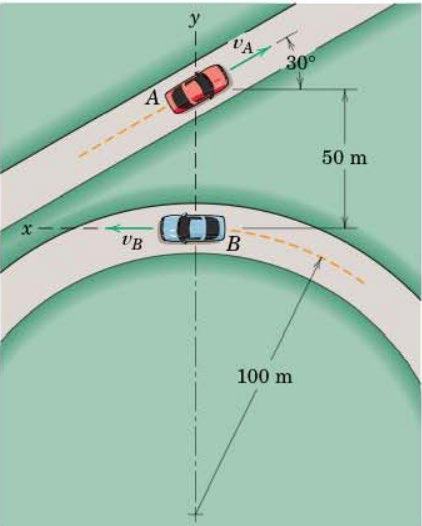

### Solution 2

1. Determine the velocity and acceleration of car A as seen by an observer moving and rotating with car B when the cars are in the position shown. The x-y axes are attached to car B.

R = 100; % m
r = 50; % m
v_a = 90/3.6; % m/s
v_b = 90/3.6; % m/s
r_I_dot = [-v_a*cosd(30);v_a*sind(30);0]; % -v_a*cos(30) i^ + v_a*sin(30) j^ m/s
r_B_I_dot = [v_b;0;0]; % v_b i^ m/s
W_B_I = [0;0;-r_B_I_dot(1)/R]; % v_B/R k^ rad/s
r_B = [0;r;0]; % r j^ m
r_B_dot = r_I_dot - r_B_I_dot - cross(W_B_I, r_B);
fprintf("Instantaneous velocity (m/s) of car A w.r.t. car B is:\n%.4f i\n%.4f\t j\n%.4f\t k", ...
        r_B_dot(1),r_B_dot(2),r_B_dot(3));

Instantaneous velocity (m/s) of car A w.r.t. car B is:
-59.1506 i
12.5000	 j
0.0000	 k

r_I_dot_dot = [0;0;0]; % 0 m/s^2
r_B_I_dot_dot = [0;-r_B_I_dot(1)^2/R;0]; % -v_B^2/R j^ m/s^2
W_B_I_dot = [0;0;0]; % 0 m/s^2
r_B_dot_dot = r_I_dot_dot - r_B_I_dot_dot - cross(W_B_I, cross(W_B_I, r_B)) - cross(W_B_I_dot, r_B) - 2*cross(W_B_I, r_B_dot);
fprintf("Instantaneous acceleration (m/s^2) of car A w.r.t. car B is:\n%.4f\t i\n%.4f j\n%.4f\t k", ...
        r_B_dot_dot(1),r_B_dot_dot(2),r_B_dot_dot(3));

Instantaneous acceleration (m/s^2) of car A w.r.t. car B is:
-6.2500	 i
-20.2003 j
0.0000	 k

2. Is this apparent velocity the negative of the velocity which B appears to have to a nonrotating observer in car A. If not, Explain the reason?

% Calculate velocity of car B w.r.t. car A (expressed w.r.t. car B)
v_a = 90/3.6; % m/s
v_b = 90/3.6; % m/s
v_a = [-v_a*cosd(30);v_a*sind(30);0]; % -v_a*cos(30) i^ + v_a*sin(30) j^ m/s
v_b = [v_b;0;0]; % v_b i^ m/s
v_b_a = v_b - v_a;
fprintf("Instantaneous velocity (m/s) of car B w.r.t. car A is:\n%.4f\t i\n%.4f j\n%.4f\t k", ...
        v_b_a(1),v_b_a(2),v_b_a(3));

Instantaneous velocity (m/s) of car B w.r.t. car A is:
46.6506	 i
-12.5000 j
0.0000	 k

% Calculate negative of the velocity which car A appears to have to a non-rotating observer in car B (expressed w.r.t. car B)
v_a = 90/3.6; % m/s
v_b = 90/3.6; % m/s
r_I_dot_nonrot = [-v_a*cosd(30);v_a*sind(30);0]; % -v_a*cos(30) i^ + v_a*sin(30) j^ m/s
r_B_I_dot_nonrot = [v_b;0;0]; % v_b i^ m/s
r_B_dot_nonrot = r_I_dot_nonrot - r_B_I_dot_nonrot;
fprintf("Negative of the velocity of car A w.r.t. non-rotating observer in car B is:\n%.4f\t i\n%.4f j\n%.4f\t k", ...
        -r_B_dot_nonrot(1),-r_B_dot_nonrot(2),-r_B_dot_nonrot(3));

Negative of the velocity of car A w.r.t. non-rotating observer in car B is:
46.6506	 i
-12.5000 j
-0.0000	 k

***Note******:*** The instantaneous velocity of car B w.r.t. car A (expressed w.r.t. car B) is equal to the negative of velocity which car A appears to have to a ***non-rotating observer*** in car B (expressed w.r.t. car B).

***Answer******:*** The instantaneous velocity of car A w.r.t. car B, will not be equal to the negative of the instantaneous velocity of car B w.r.t. car A. This is because car B is undergoing circular motion (i.e. rotating frame) and thus, we need to have additional corrective terms in order to express the velocity/acceleration of car A measured w.r.t. car B, which is/are not required when measuring velocity/acceleration of car B w.r.t. car A. This is why the results differ.

### Problem 3

Aircraft B has a constant speed of 150 m/s as it passes the bottom of a circular loop of 400-m radius. Aircraft A flying horizontally in the plane of the loop passes 100 m directly below B at a constant speed of 100 m/s.

- Determine the instantaneous velocity and acceleration which A appears to have to the pilot of B, who is fixed to his rotating aircraft.

- Compare your results for part (a) with the case of erroneously treating the pilot of aircraft B as nonrotating.

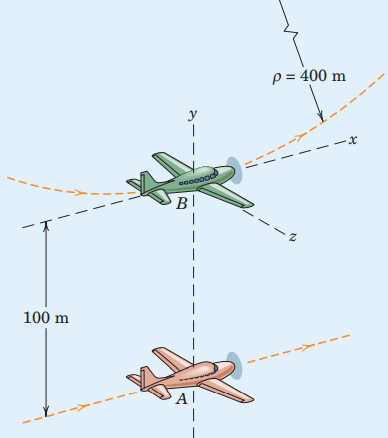

### Solution 3

1. Determine the instantaneous velocity and acceleration which A appears to have to the pilot of B, who is fixed to his rotating aircraft.

R = 400; % m
r = 100; % m
r_I_dot = [100;0;0]; % 100 i^ m/s
r_B_I_dot = [150;0;0]; % 150 i^ m/s
W_B_I = [0;0;r_B_I_dot(1)/R]; % v_B/R k^ rad/s
r_B = [0;-r;0]; % -r j^ m
r_B_dot = r_I_dot - r_B_I_dot - cross(W_B_I, r_B);
fprintf("Instantaneous velocity (m/s) of plane A w.r.t. plane B is:\n%.4f i\n%.4f\t j\n%.4f\t k", ...
        r_B_dot(1),r_B_dot(2),r_B_dot(3));

Instantaneous velocity (m/s) of plane A w.r.t. plane B is:
-87.5000 i
0.0000	 j
0.0000	 k

r_I_dot_dot = [0;0;0]; % 0 m/s^2
r_B_I_dot_dot = [0;r_B_I_dot(1)^2/R;0]; % v_B^2/R j^ m/s^2
W_B_I_dot = [0;0;0]; % 0 m/s^2
r_B_dot_dot = r_I_dot_dot - r_B_I_dot_dot - cross(W_B_I, cross(W_B_I, r_B)) - cross(W_B_I_dot, r_B) - 2*cross(W_B_I, r_B_dot);
fprintf("Instantaneous acceleration (m/s^2) of plane A w.r.t. plane B is:\n%.4f\ti\n%.4f\tj\n%.4f\tk", ...
        r_B_dot_dot(1),r_B_dot_dot(2),r_B_dot_dot(3));

Instantaneous acceleration (m/s^2) of plane A w.r.t. plane B is:
0.0000	i
-4.6875	j
0.0000	k

2. Compare your results for part (a) with the case of erroneously treating the pilot of aircraft B as nonrotating.

r_I_dot_nonrot = [100;0;0]; % 100 i^ m/s
r_B_I_dot_nonrot = [150;0;0]; % 150 i^ m/s
r_B_dot_nonrot = r_I_dot_nonrot - r_B_I_dot_nonrot;
fprintf("Instantaneous velocity (m/s) of plane A w.r.t. non-rotating observer in plane B is:\n%.4f i\n%.4f\t j\n%.4f\t k", ...
        r_B_dot_nonrot(1),r_B_dot_nonrot(2),r_B_dot_nonrot(3));

Instantaneous velocity (m/s) of plane A w.r.t. non-rotating observer in plane B is:
-50.0000 i
0.0000	 j
0.0000	 k

r_I_dot_dot_nonrot = [0;0;0]; % 0 m/s^2
r_B_I_dot_dot_nonrot = [0;r_B_I_dot_nonrot(1)^2/R;0]; % v_B_nonrot^2/R j^ m/s^2
r_B_dot_dot_nonrot = r_I_dot_dot_nonrot - r_B_I_dot_dot_nonrot;
fprintf("Instantaneous acceleration (m/s^2) of plane A w.r.t. non-rotating observer in plane B is:\n%.4f\t i\n%.4f j\n%.4f\t k", ...
        r_B_dot_dot_nonrot(1),r_B_dot_dot_nonrot(2),r_B_dot_dot_nonrot(3));

Instantaneous acceleration (m/s^2) of plane A w.r.t. non-rotating observer in plane B is:
0.0000	 i
-56.2500 j
0.0000	 k

r_B_dot_error = r_B_dot-r_B_dot_nonrot;
fprintf("Error in computing instantaneous velocity (m/s) of plane A w.r.t. rotating/non-rotating observer in plane B is:\n%.4f i\n%.4f\t j\n%.4f\t k", ...
        r_B_dot_error(1),r_B_dot_error(2),r_B_dot_error(3));

Error in computing instantaneous velocity (m/s) of plane A w.r.t. rotating/non-rotating observer in plane B is:
-37.5000 i
0.0000	 j
0.0000	 k

r_B_dot_dot_error = r_B_dot_dot-r_B_dot_dot_nonrot;
fprintf("Error in computing instantaneous acceleration (m/s^2) of plane A w.r.t. rotating/non-rotating observer in plane B is:\n%.4f\ti\n%.4f\tj\n%.4f\tk", ...
        r_B_dot_dot_error(1),r_B_dot_dot_error(2),r_B_dot_dot_error(3));

Error in computing instantaneous acceleration (m/s^2) of plane A w.r.t. rotating/non-rotating observer in plane B is:
0.0000	i
51.5625	j
0.0000	k

The resulting instantaneous velocity and acceleration of plane A w.r.t. plane B, when considering plane B to be rotating and non-rotating respectively, are not the same since plane B cannot be considered an inertial frame when it is undergoing circular motion. Thus, we need to have additional corrective terms in order to express the velocity/acceleration of plane A measured w.r.t. plane B, which is why the results differ.

### Problem 4

Consider the following Bicycle Model vehicle:

- Mass: 2100 kg

- Wheelbase: 3.3 m

- Weight Distribution: Defined below

- Front Cornering Stiffness: −78.9 kN/rad

- Rear Cornering Stiffness: −77.5 kN/rad

This vehicle is being driven on a 144 m radius (left turn) skid pad at ever increasing speed, from zero to 78 mph.

For the weight distributions 38% front (a=2.046 m, b=1.254 m), 50% front (a=1.65 m, b=1.65 m), and 62% front (a=1.254 m, b=2.046 m), answer the following:

- Plot Front Slip Angle vs. Lateral Acceleration

- Plot Rear Slip Angle vs. Lateral Acceleration

- Plot Vehicle Sideslip Angle (β) vs. Lateral Acceleration

- Plot Steer Angle vs. Lateral Acceleration

You should plot the results for all three models in one figure for each of the questions.

### Solution 4

% Given data
m = 2100; % kg
l = 3.3; % m
c_alpha_F = 78.9e3; % N/rad (adapted ISO convention)
c_alpha_R = 77.5e3; % N/rad (adapted ISO convention)
R = 144; % m
v = 0:1e-4:(78*0.44704); % m/s
a_1 = 2.046; b_1 = 1.254; % m (for 38% front weight distribution)
a_2 = 1.650; b_2 = 1.650; % m (for 50% front weight distribution)
a_3 = 1.254; b_3 = 2.046; % m (for 62% front weight distribution)
% Calculate lateral acceleration and lateral force
a_y = (v.^2/R); % Adapted ISO convention
F_y = m*a_y;

1. Plot Front Slip Angle vs. Lateral Acceleration

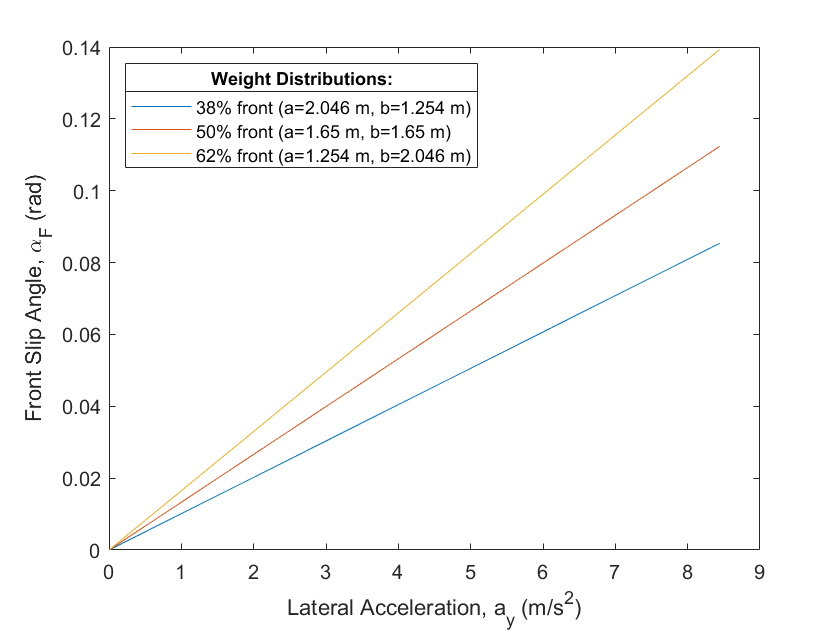

F_y_F_1 = (b_1/l)*F_y;
alpha_F_1 = F_y_F_1/c_alpha_F;
F_y_F_2 = (b_2/l)*F_y;
alpha_F_2 = F_y_F_2/c_alpha_F;
F_y_F_3 = (b_3/l)*F_y;
alpha_F_3 = F_y_F_3/c_alpha_F;
figure(1)
plot(a_y,alpha_F_1)
hold on
plot(a_y,alpha_F_2)
plot(a_y,alpha_F_3)
hold off
xlabel("Lateral Acceleration, a_y (m/s^2)")
ylabel("Front Slip Angle, \alpha_F (rad)")
lgd = legend("38% front (a=2.046 m, b=1.254 m)", "50% front (a=1.65 m, b=1.65 m)", "62% front (a=1.254 m, b=2.046 m)",'Location','NW');
title(lgd,'Weight Distributions:')

2. Plot Rear Slip Angle vs. Lateral Acceleration

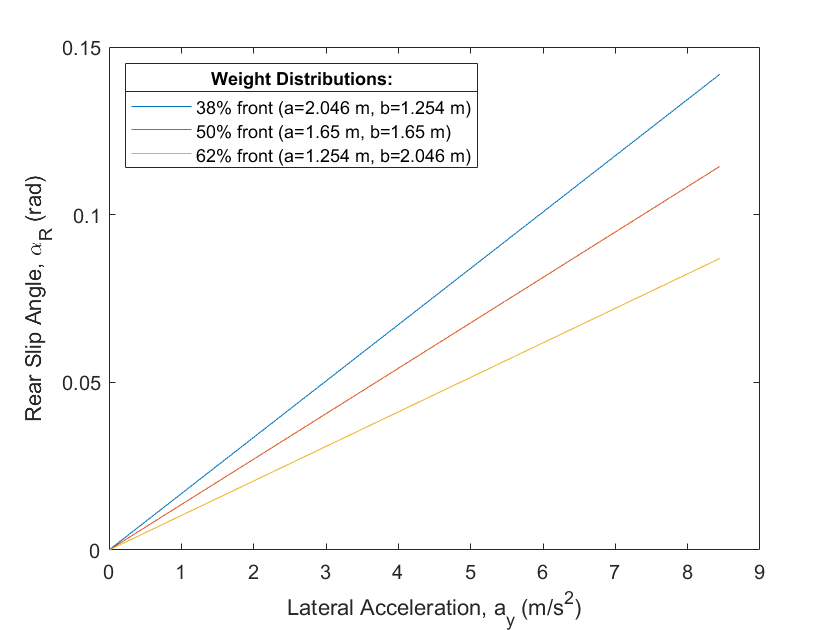

F_y_R_1 = (a_1/l)*F_y;
alpha_R_1 = F_y_R_1/c_alpha_R;
F_y_R_2 = (a_2/l)*F_y;
alpha_R_2 = F_y_R_2/c_alpha_R;
F_y_R_3 = (a_3/l)*F_y;
alpha_R_3 = F_y_R_3/c_alpha_R;
figure(2)
plot(a_y,alpha_R_1)
hold on
plot(a_y,alpha_R_2)
plot(a_y,alpha_R_3)
hold off
xlabel("Lateral Acceleration, a_y (m/s^2)")
ylabel("Rear Slip Angle, \alpha_R (rad)")
lgd = legend("38% front (a=2.046 m, b=1.254 m)", "50% front (a=1.65 m, b=1.65 m)", "62% front (a=1.254 m, b=2.046 m)",'Location','NW');
title(lgd,'Weight Distributions:')

3. Plot Vehicle Sideslip Angle (β) vs. Lateral Acceleration

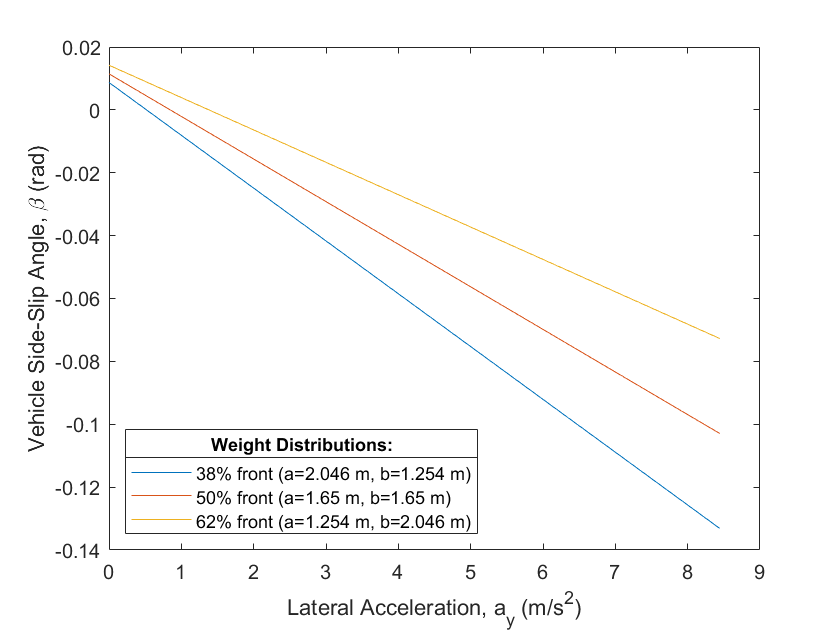

beta_1 = abs(b_1/R)-abs(alpha_R_1); % Adapted ISO convention
beta_2 = abs(b_2/R)-abs(alpha_R_2); % Adapted ISO convention
beta_3 = abs(b_3/R)-abs(alpha_R_3); % Adapted ISO convention
figure(3)
plot(a_y,beta_1)
hold on
plot(a_y,beta_2)
plot(a_y,beta_3)
hold off
xlabel("Lateral Acceleration, a_y (m/s^2)")
ylabel("Vehicle Side-Slip Angle, \beta (rad)")
lgd = legend("38% front (a=2.046 m, b=1.254 m)", "50% front (a=1.65 m, b=1.65 m)", "62% front (a=1.254 m, b=2.046 m)",'Location','SW');
title(lgd,'Weight Distributions:')

4. Plot Steer Angle vs. Lateral Acceleration

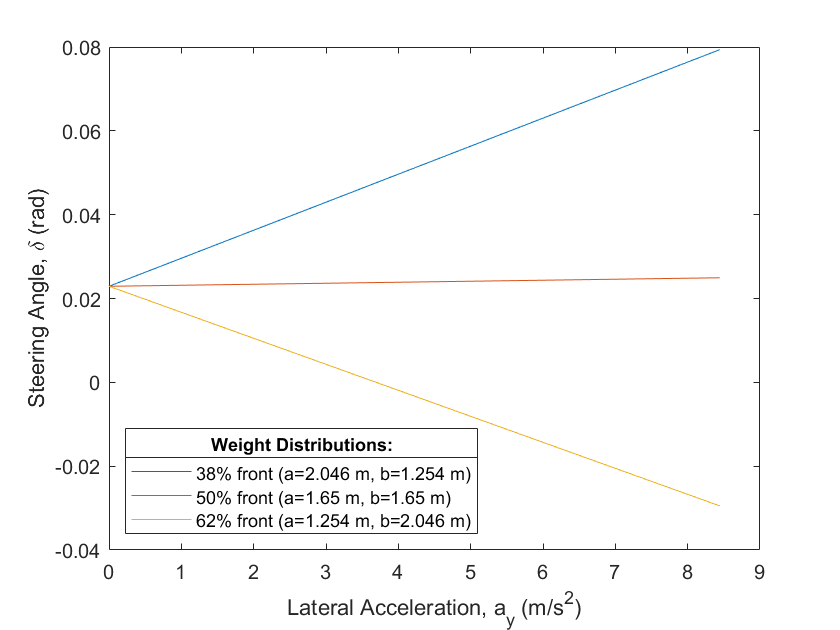

delta_1 = abs(l/R) - abs(alpha_F_1) + abs(alpha_R_1); % Adapted ISO convention
delta_2 = abs(l/R) - abs(alpha_F_2) + abs(alpha_R_2); % Adapted ISO convention
delta_3 = abs(l/R) - abs(alpha_F_3) + abs(alpha_R_3); % Adapted ISO convention
figure(4)
plot(a_y,delta_1)
hold on
plot(a_y,delta_2)
plot(a_y,delta_3)
hold off
xlabel("Lateral Acceleration, a_y (m/s^2)")
ylabel("Steering Angle, \delta (rad)")
lgd = legend("38% front (a=2.046 m, b=1.254 m)", "50% front (a=1.65 m, b=1.65 m)", "62% front (a=1.254 m, b=2.046 m)",'Location','SW');
title(lgd,'Weight Distributions:')